clear
clc

% СОЗДАНИЕ ОБЪЕКТА IF97 (свойства воды и пара)
javaaddpath if97.jar
unitSystem  =  javaMethod('valueOf', 'com.hummeling.if97.IF97$UnitSystem', 'ENGINEERING');
if97  =  com.hummeling.if97.IF97(unitSystem);

единицы измерения величин:

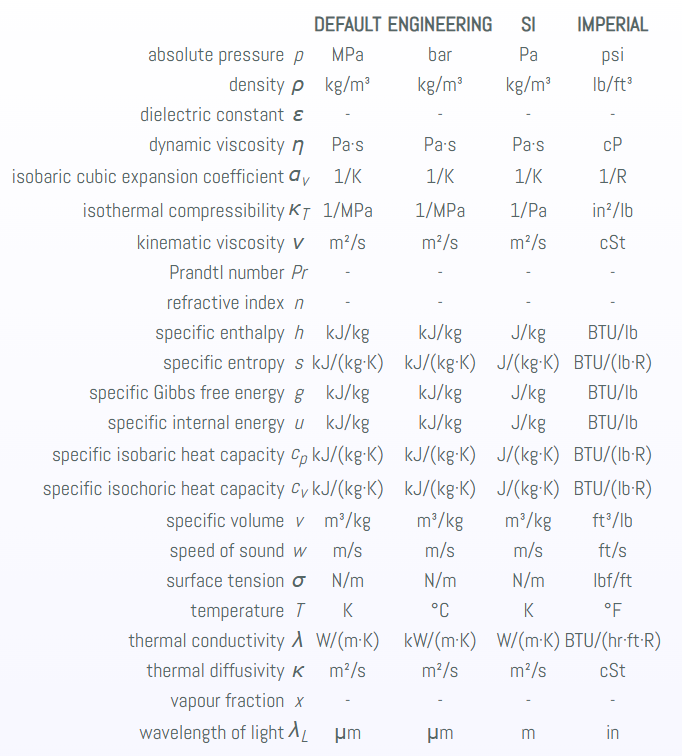

## Исходные данные

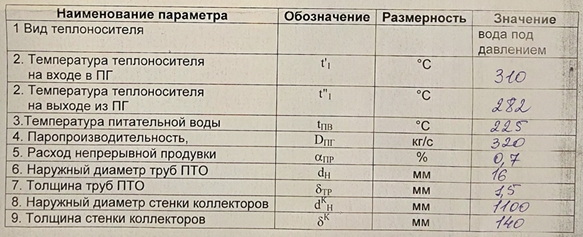

coolantTempIn = 310; % температура теплоносителя вход (t'1), °С
coolantTempOut = 282; % температура теплоносителя в выход (t''1), °С
feedwaterTempIn = 225; % темп-ра питательной воды (tпв), °С
steaming = 320; % паропроизводительность (Dпг), кг/с
continiousBlowConsumption = 0.7; % расход непрерывной продувки (αпр), %
ptoDiamOutside = 16; % наружный диаметр труб ПТО (dн), мм
ptoThickness = 1.5; %толщина труб ПТО (δтр), мм
collectorDiamOutside = 1100; % наружный диаметр стенки коллекторов (dkн), мм
collectorThickness = 140; % толщина стенки коллекторов (δк), мм

## Тепловой расчет ПГ

### 2.3.1 Теплофизические характеристики теплоносителя

boilingMargin =20; % запас до кипения (Δtзап), °С
coolantTempSat = coolantTempIn + boilingMargin; % темп-ра насыщения (t1s), °С
coolantPresSat = if97.saturationPressureT(coolantTempSat); % давление при насыщении(p1), °С
coolantTemp = (coolantTempIn + coolantTempOut) / 2; % средняя темп-ра (t1_), °С 
coolantDensity = if97.densityPT(coolantPresSat, coolantTemp); % средняя плотность (ρ1), кг/м^3
coolantDynamicVisc = if97.dynamicViscosityPT(coolantPresSat, coolantTemp); % дин. вязкость (μ1), Па*с
coolantKinematicVisc = coolantDynamicVisc / coolantDensity; % кин. вязкость (ν1), м^2/с
coolantThermalConductivity = if97.thermalConductivityPT(coolantPresSat, coolantTemp); % средняя теплопроводность (λ1), кВт/(м*°С)
coolantHeatCapacity = if97.isobaricHeatCapacityPT(coolantPresSat, coolantTemp); % средняя теплоемкость (cp1), кДж/(кг*°С)
coolantPrandtl = if97.PrandtlPT(coolantPresSat, coolantTemp); % число Прандтля

%вывод результата:
run out231.m

Температура насыщения теплоносителя (t1s), °С:  330.0 
Давление теплоносителя при температуре насыщения (p1), бар:  128.58 
Средняя температура теплоносителя в трубках ПТО (t1_), °С:  296.0 
Средняя плотность теплоносителя в трубках ПТО (ρ1), кг/м^3:  729.74 
Коэффициент динамической вязкости теплоносителя (μ1), Па*с:  8.917e-05 
Коэффициент кинематической вязкости теплоносителя (ν1), м^2/с:  1.222e-07 
Средняя теплопроводность теплоносителя (λ1), Вт/(м*°C):  0.562 
Изобарная теплоёмкость теплоносителя (cp1), кДж/(кг*°C):  5.45 
Число Прандтля для теплоносителя (Pr1):  0.865 


### 2.3.2 Теплофизические характеристики рабочего тела

minHeating = 10; % минимальный температурный напор (δt), °С
x2 = 0.998; % степень сухости генерируемого пара

feedwaterTempSat = coolantTempOut - minHeating; % температура насыщения рабочего тела в объеме ПГ (t2s), °С
feedwaterPres = if97.saturationPressureT(feedwaterTempSat); %давление рабочего тела (p2), бар
feedwaterEnthalpyIn = if97.specificEnthalpyPT(feedwaterPres, feedwaterTempIn); % энтальпия питательной воды на входе в ПГ (hпв), кДж/кг
purgewaterEnthalpy = if97.specificEnthalpySaturatedLiquidP(feedwaterPres); % энтальпия продувочной воды (hпр = h'), кДж/кг
saturatedSteamEnthalpy = if97.specificEnthalpySaturatedVapourP(feedwaterPres); % энтальпия сухого насыщенного пара при давлении p2 (h''2), кДж/кг
feedwaterEnthalpyOut = saturatedSteamEnthalpy * x2 + purgewaterEnthalpy * (1 - x2); % энтальпия осушенного пара на выходе из ПГ (h2), кДж/кг
feedwaterVolumeOut = if97.specificVolumeSaturatedVapourP(feedwaterPres) * x2 + if97.specificVolumeSaturatedLiquidP(feedwaterPres) * (1 - x2); % удельный объём пара на выходе из ПГ (v2), м^3 /кг
feedwaterDensityOut = 1 / feedwaterVolumeOut; % плотность пара на выходе из ПГ (ρ2), кг/м3
feedwaterDensityIn = if97.densityPT(feedwaterPres, feedwaterTempIn); % Плотность питательной воды на входе в ПГ (ρпв), кг/м3

%вывод результата:
run out232.m

Температура насыщения (t2s), °С:  272.0 
Давление рабочего тела в ПГ (p2), бар:  56.77 
Энтальпия питательной воды на входе в ПГ (hпв), кДж/кг:  967.59 
Энтальпия продувочной воды (hпр = h'), кДж/кг:  1195.30 
Энтальпия сухого насыщенного пара при давлении рабочего тела p2 (h''), кДж/кг:  2787.96 
Энтальпия осушенного пара на выходе из ПГ (h2), кДж/кг:  2784.78 
Удельный объём пара на выходе из ПГ (v2), м^3 /кг:  0.034 
Плотность пара на выходе из ПГ (ρ2), кг/м^3 :  29.08 
Плотность питательной воды на входе в ПГ (ρпв), кг/м^3:  836.61 


### 2.3.3 Материальный и тепловой балансы ПГ

efficiency =0.985; % КПД ПГ (ηпг)

continiousBlow = continiousBlowConsumption * steaming / 100; % Величина непрерывной продувки ПГ (Dпр), кг/с
feedwaterConsumption = steaming + continiousBlow; % Расход питательной воды, подаваемой в ПГ (Dпв), кг/с 
feedwaterHeat = steaming * (feedwaterEnthalpyOut - feedwaterEnthalpyIn) + continiousBlow * (purgewaterEnthalpy - feedwaterEnthalpyIn); % Количество теплоты, получаемое рабочим телом в ПГ (Q2), кВт
coolantHeat = feedwaterHeat / efficiency; % Количество теплоты, передаваемое теплоносителем в ПГ (Q1), кВт
coolantConsumption = coolantHeat / (coolantHeatCapacity * (coolantTempIn - coolantTempOut)); % Расход теплоносителя через трубную систему поверхности теплообмена ПГ (G1), кг/с

%вывод результата:
run out233.m

Величина непрерывной продувки ПГ (Dпр), кг/с:  2.24 
Расход питательной воды, подаваемой в ПГ (Dпв), кг/с:  322.24 
Количество теплоты, получаемое рабочим телом в ПГ (Q2), кВт:  582010.85 
Количество теплоты, передаваемое теплоносителем в ПГ (Q1), кВт:  590873.96 
Расход теплоносителя через трубную систему поверхности теплообмена ПГ (G1), кг/с:  3870.73 


### 2.3.4. Расчёт коэффициента теплопередачи

thermalResist = 3* 1e-5; % Термическое сопротивление (Rзагр), 10^-5 м^2*°C/Вт
